# LeRoy Analysis

## Summary

clear all; load leroy.mat

## Histograms of the data distribution

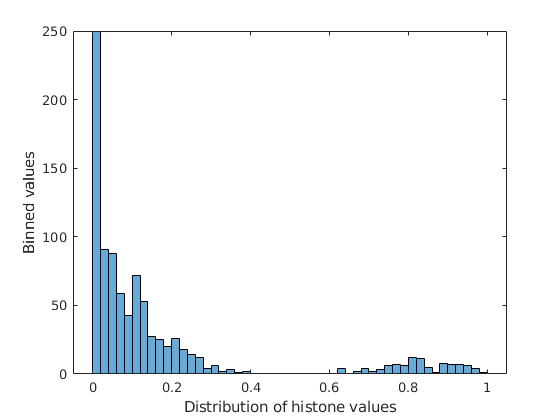

figure;
histogram(rescale(leroy_val), 50);
xlabel('Distribution of histone values');
ylabel('Binned values');

## Boxplots of the data distribution

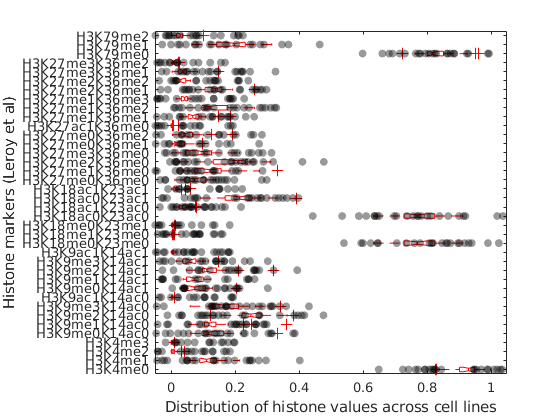

tmp = ones([length(leroy_cellline), length(leroy_mark)-1]) .* [1:length(leroy_mark)-1];

figure;
% Boxplot showing distribution of each histone marker
boxplot(rescale(leroy_val), ...
    'orientation', 'horizontal', ...
    'Notch', 'on', 'Colors', 'r', ...
    'OutlierSize', 8, 'jitter', 0.05);
yticklabels(leroy_mark(2:end))
hold on;

% Categorical scatter plot imposed on boxplot
for j = 1:length(leroy_mark)-1
    scatter(leroy_val(:, j), tmp(:, j), ...
        'k', 'filled', ...
        'MarkerFaceAlpha', 0.4, ...
        'jitter', 0.05)
end
xlabel('Distribution of histone values across cell lines');
ylabel('Histone markers (Leroy et al)');

## Simulating effect of metabolic state on methylation

initCobraToolbox; changeCobraSolver('gurobi', 'all');



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2020
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.25.4).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

load 05042020eGEM.mat; model = eGEM;

% Turn off reactions that negatively affect model performance.
posToTurnOff = find(ismember(model.rxns, {'ALR', 'MGSA', 'MGSA2'}));
model.ub(posToTurnOff) = 0; model.lb(posToTurnOff) = 0;
model.lb(ismember(model.rxns, 'biomass_objective')) = 0; % Change the lower bound of the biomass objective function to 0. 

% Reset the primary objective function
model.c = zeros(size(model.c));
model.c(ismember(model.rxns, 'biomass_objective')) = 1;

mediumMap = 'FINAL_MEDIUM_MAP.xlsx';
reactions_to_optimize = ["DM_KAC", "DM_KMe1", "DM_KMe2", "DM_KMe3"];
model.lb(ismember(model.rxns, reactions_to_optimize)) = 0;
model.rev(ismember(model.rxns, reactions_to_optimize)) = 0;

load mediumPerturbation.mat mediumPerturbationIDs
load zeta_sra.mat


## Metabolic modeling predicts bulk methylation in diverse cancer cell lines